# HRclass Tutorial

        基于HRclass实现石墨烯model      

        2021.08

- Author: parkman

- Email：parkman@buaa.edu.cn

**目录**

syms t real;
Grpahene_TB = HR(2);
A_vectorL = [0,0,0;1,0,0;0,-1,0];
B_vectorL = [0,0,0;-1,0,0;0,1,0];

Grpahene_TB = Grpahene_TB.set_hop(t,1,2,A_vectorL,'sym');
Grpahene_TB = Grpahene_TB.set_hop(t,2,1,B_vectorL,'sym')

Grpahene_TB =   HR - 属性:

        vectorL: [5×3 int32]
          HnumL: [2×2×5 double]
          HcoeL: [2×2×5 sym]
          NRPTS: 5
        WAN_NUM: 2
       Line_000: 1
      Basis_num: []
             Rm: [3×3 double]
             Gk: [3×3 double]
    symvar_list: [1×1 sym]


Grpahene_TB.printout;

   0   0   0



$$\left(\begin{array}{cc} 0 & t\\ t & 0 \end{array}\right)$$

   1   0   0



$$\left(\begin{array}{cc} 0 & t\\ 0 & 0 \end{array}\right)$$

    0   -1    0



$$\left(\begin{array}{cc} 0 & t\\ 0 & 0 \end{array}\right)$$

   -1    0    0



$$\left(\begin{array}{cc} 0 & 0\\ t & 0 \end{array}\right)$$

   0   1   0



$$\left(\begin{array}{cc} 0 & 0\\ t & 0 \end{array}\right)$$

Grpahene_TB_list = Grpahene_TB.rewrite()

Grpahene_TB_list =   HR - 属性:

        vectorL: [6×5 int32]
          HnumL: [6×1 double]
          HcoeL: [6×1 sym]
          NRPTS: 6
        WAN_NUM: 2
      Basis_num: []
             Rm: [3×3 double]
             Gk: [3×3 double]
    symvar_list: [1×1 sym]


Grpahene_TB_list.list()

# R1 R2 R3 i j real imag


$$\left(\begin{array}{ccccccc} 0 & 0 & 0 & 2 & 1 & t & 0\\ 0 & 0 & 0 & 1 & 2 & t & 0\\ 1 & 0 & 0 & 1 & 2 & t & 0\\ 0 & -1 & 0 & 1 & 2 & t & 0\\ -1 & 0 & 0 & 2 & 1 & t & 0\\ 0 & 1 & 0 & 2 & 1 & t & 0 \end{array}\right)$$

$$ans = \left(\begin{array}{ccccccc} 0 & 0 & 0 & 2 & 1 & t & 0\\ 0 & 0 & 0 & 1 & 2 & t & 0\\ 1 & 0 & 0 & 1 & 2 & t & 0\\ 0 & -1 & 0 & 1 & 2 & t & 0\\ -1 & 0 & 0 & 2 & 1 & t & 0\\ 0 & 1 & 0 & 2 & 1 & t & 0 \end{array}\right)$$

Rm = [1,0,0;-0.5,sqrt(3)/2,0;0,0,1];
Grpahene_TB_list = Grpahene_TB_list.input_Rm(Rm);
orbL = [2/3,1/3,0;1/3,2/3,0];
Grpahene_TB_list.orbL = orbL;

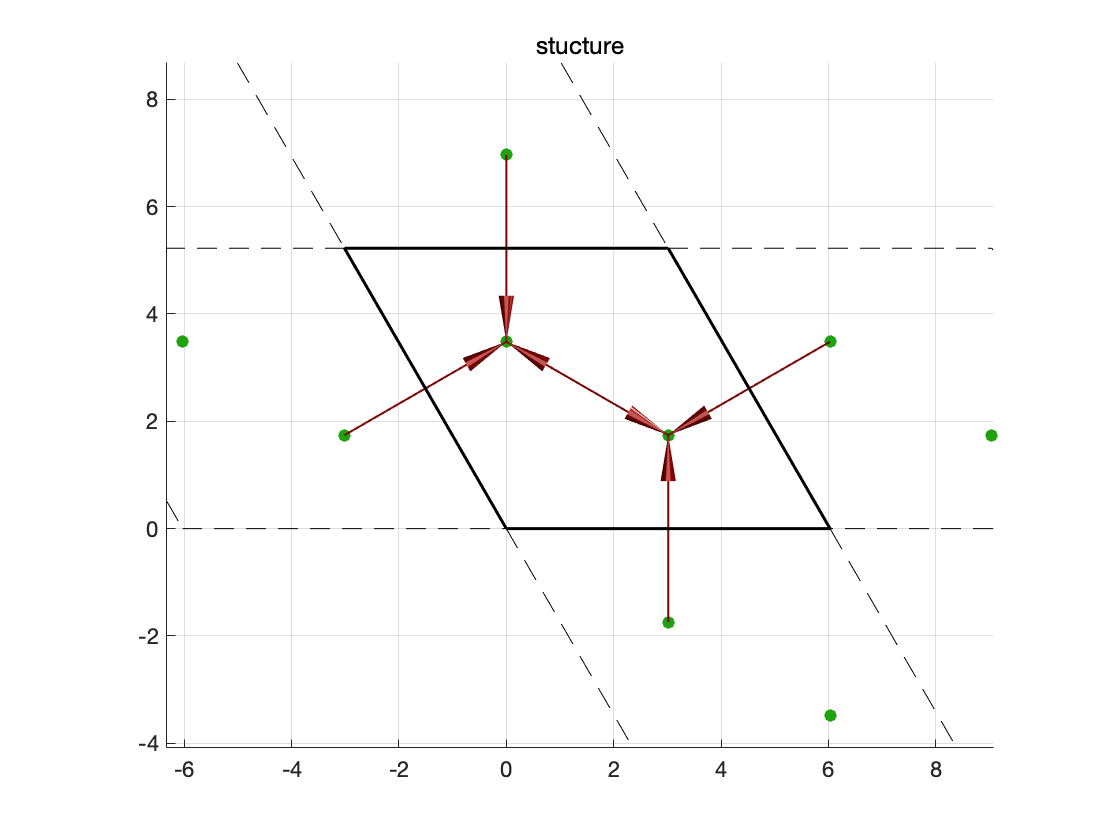

Grpahene_TB_list.show('HOPPING','scale', 2.4560000896,'atomscale',1,'TwoD',true);